% 6G THz BPSK Signal Detection using k-NN (Optimized)
clc; clear;

% Parameters
N = 1e5;                          % Number of bits
SNR_dB_range = 0:2:30;           % SNR values in dB
ber_baseline = zeros(size(SNR_dB_range));  % Traditional BER
ber_ML = zeros(size(SNR_dB_range));        % ML (k-NN) BER
path_loss = 10;                  % Simple path loss factor (adjustable)

% Generate random bitstream
data = randi([0 1], N, 1);

% BPSK modulation: 0 -> -1, 1 -> +1
modulated_signal = 2*data - 1;

for i = 1:length(SNR_dB_range)
    SNR_dB = SNR_dB_range(i);
    SNR_linear = 10^(SNR_dB/10);
    noise_power = 1 / SNR_linear;
    
    % Channel model (AWGN with path loss)
    noise = sqrt(noise_power/2) * randn(N, 1);  % Real noise
    received_signal = (modulated_signal / sqrt(path_loss)) + noise;
    
    %% === Traditional Detection (Zero-Forcing style thresholding) ===
    estimated = received_signal * sqrt(path_loss); % Reverse path loss
    detected_bits = estimated > 0;
    ber_baseline(i) = sum(detected_bits ~= data) / N;
    
    %% === ML Detection using k-NN ===
    % Prepare features (1D signal input)
    X = received_signal;    % Feature: noisy signal
    Y = data;               % Labels

    % Split: 80% train, 20% test
    split_idx = floor(0.8 * N);
    X_train = X(1:split_idx, :);
    Y_train = Y(1:split_idx);
    X_test  = X(split_idx+1:end, :);
    Y_test  = Y(split_idx+1:end);

    % Train k-NN classifier
    mdl = fitcknn(X_train, Y_train, ...
                  'NumNeighbors', 5, ...
                  'Distance', 'euclidean');

    % Predict
    pred = predict(mdl, X_test);
    ber_ML(i) = sum(pred ~= Y_test) / length(Y_test);
    
    % Optional: Display progress
    fprintf('SNR = %2d dB | BER-kNN: %.4f | BER-ZF: %.4f\n', ...
            SNR_dB, ber_baseline(i), ber_ML(i));
end

SNR =  0 dB | BER-kNN: 0.3291 | BER-ZF: 0.3764
SNR =  2 dB | BER-kNN: 0.2905 | BER-ZF: 0.3356
SNR =  4 dB | BER-kNN: 0.2407 | BER-ZF: 0.2798
SNR =  6 dB | BER-kNN: 0.1860 | BER-ZF: 0.2071
SNR =  8 dB | BER-kNN: 0.1294 | BER-ZF: 0.1474
SNR = 10 dB | BER-kNN: 0.0793 | BER-ZF: 0.0886
SNR = 12 dB | BER-kNN: 0.0377 | BER-ZF: 0.0415
SNR = 14 dB | BER-kNN: 0.0129 | BER-ZF: 0.0143
SNR = 16 dB | BER-kNN: 0.0023 | BER-ZF: 0.0027
SNR = 18 dB | BER-kNN: 0.0002 | BER-ZF: 0.0003
SNR = 20 dB | BER-kNN: 0.0000 | BER-ZF: 0.0000
SNR = 22 dB | BER-kNN: 0.0000 | BER-ZF: 0.0000
SNR = 24 dB | BER-kNN: 0.0000 | BER-ZF: 0.0000
SNR = 26 dB | BER-kNN: 0.0000 | BER-ZF: 0.0000
SNR = 28 dB | BER-kNN: 0.0000 | BER-ZF: 0.0000
SNR = 30 dB | BER-kNN: 0.0000 | BER-ZF: 0.0000


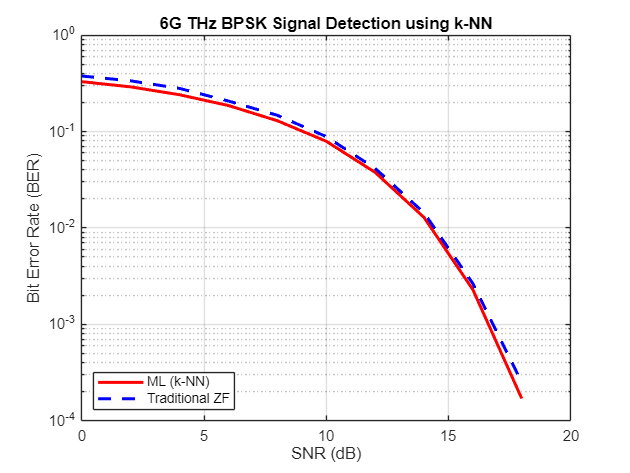

%% === Plot Results ===
figure;
semilogy(SNR_dB_range, ber_baseline, 'r-', 'LineWidth', 2); hold on;
semilogy(SNR_dB_range, ber_ML, 'b--', 'LineWidth', 2);
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('6G THz BPSK Signal Detection using k-NN');
legend('ML (k-NN)', 'Traditional ZF', 'Location', 'southwest');
grid on;
ylim([1e-4 1]);
saveas(gcf, 'kNN.eps', 'epsc');  % 'epsc' for color EPS